Se carga la imagen y se crea un histograma especificado

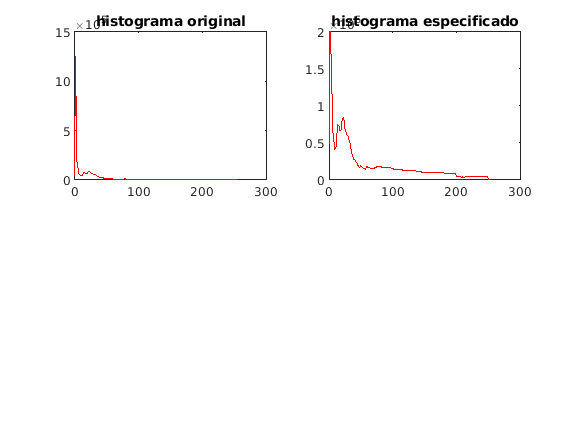

I = imread("im.jpg");
Im = rgb2gray(I);

[M,N] = size(Im);
[n_j,r_k]=imhist(Im);

p_q=n_j;
p_q = cambiohitograma(1,5,50,250,600000,p_q);
p_q = cambiohitograma(1,255,60,200,200000,p_q);

figure
subplot(2,2,1);
plot(0:255, n_j, 'Red');title("histograma original")
subplot(2,2,2);
plot(0:255, p_q, 'Red');title("histograma especificado")

Se verifica que el nuevo histograma mantenga la misma cantidad de pixeles

sum(p_q)

ans = 5298545

M*N

ans = 5298545

Se aplica la ecualizacion con el histograma especificado y se comparan los resultados

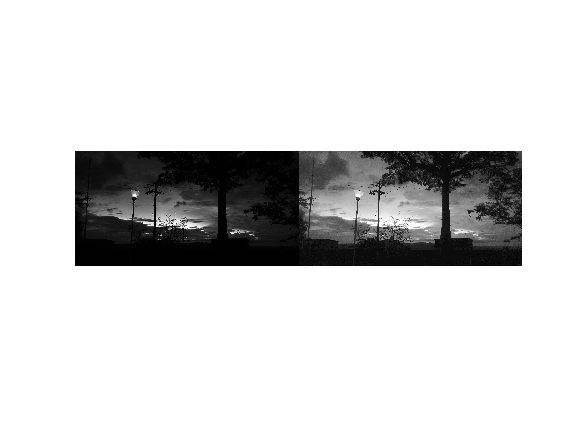

[Im2,G_z,r_k]=ecualizacion2(Im,p_q);

figure
imshow(cat(2,Im,Im2))

se muestra el histograma de la nueva imagen y la función de cambio

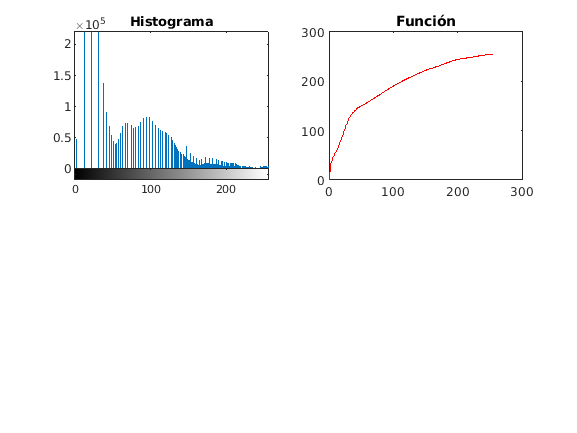

figure
subplot(2,2,1);
imhist(Im2); title("Histograma")
subplot(2,2,2);
plot(0:255, G_z, 'Red');title("Función")

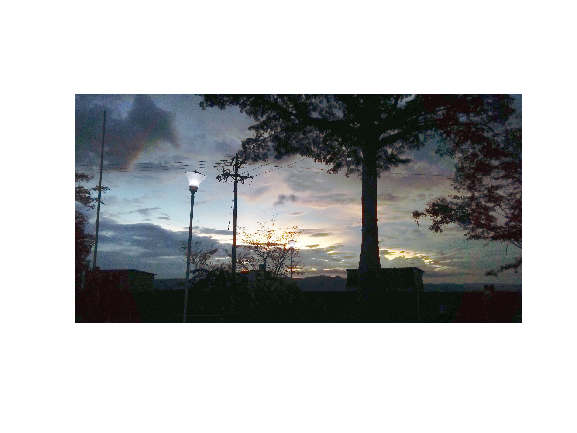

I = imread("im.jpg");

[n_jR,r_k]=imhist(I(:,:,1));
[n_jG,r_k]=imhist(I(:,:,2));
[n_jB,r_k]=imhist(I(:,:,3));

p_qR=n_jR;
p_qR = cambiohitograma(1,5,50,250,600000,p_qR);
p_qR = cambiohitograma(1,255,60,200,200000,p_qR);

p_qG=n_jG;
p_qG = cambiohitograma(1,5,50,250,600000,p_qG);
p_qG = cambiohitograma(1,255,60,200,200000,p_qG);

p_qB=n_jB;
p_qB = cambiohitograma(1,5,50,250,600000,p_qB);
p_qB = cambiohitograma(1,255,60,200,200000,p_qB);

[ImR,G_zR,r_k]=ecualizacion2(I(:,:,1),p_qR);
[ImG,G_zG,r_k]=ecualizacion2(I(:,:,2),p_qG);
[ImB,G_zB,r_k]=ecualizacion2(I(:,:,3),p_qB);
figure
imshow(cat(3,ImR,ImG,ImB))